此处简要介绍一些独特的招牌功能

# Database

不依赖 MATLAB Database Toolbox 的数据库功能，目前仅支持MariaDB

建立数据库连接

Connection=MATLAB.Database.MariaDB('Data-Server-2','TransferLearning','ReadOnly','');

SampleData=load('+MATLAB\+Database\示例数据.mat');

将表插入数据库，或更新现有表：

Connection.UpdateByPrimary('Blocks',SampleData.Blocks);

无法解析名称 'SampleData.Blocks'。

将数据库中所有表导出

DataDict=Connection.Dump;

下载完成，反序列化……
已完成2/8：Cells
已完成8/8：脑区
已完成6/8：小鼠基本
已完成4/8：_MATLAB_类型
已完成5/8：实验日志
已完成1/8：Blocks
已完成7/8：病毒注射与玻片观察
已完成3/8：Trials


# General

## PathManager

安装搜索路径管理系统

MATLAB.General.PathManager.Setup;

设置共享路径

MATLAB.General.PathManager.AddSharedPaths('C:\Users\vhtmf\Documents\MATLAB\MATLAB-Extension')

卸载搜索路径管理系统

MATLAB.General.PathManager.Uninstall;

## Pointer

import MATLAB.General.SharedPtr
%分配内存空间并填充初始值
P1=SharedPtr.Allocate(FillData=1:10);

%读出类型可以和写入不一致
P1.Read(10,MATLAB.DataTypes.ArrayType.UINT8)

ans = 10×1 uint8 列向量
     0
     0
     0
     0
     0
     0
   240
    63
     0
     0


%分配空间但不填充值
P2=SharedPtr.Allocate(NumBytes=80);
%指针拷贝
SharedPtr.Copy(P2,P1,80);
P2.Read(10,MATLAB.DataTypes.ArrayType.DOUBLE)

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


# Graphics

## Window

列出可用屏幕

S=MATLAB.Graphics.Window.Screens

S = 1×4 table
      DeviceName               Description                      Rectangle            IsPrimary
    ______________    ______________________________    _________________________    _________

    "\\.\DISPLAY1"    "Intel(R) Iris(R) Xe Graphics"    0       0    2400    1600      true   


显示图像

[I,~,A]=imread('工具箱图像.png');
I=gather(permute(cat(3,uint8(single(I(:,:,[3,2,1])).*single(A)/255),A),[3,2,1]));

创建窗口

W1=MATLAB.Graphics.Window.Create(DeviceName=S.DeviceName(1),PositionXY=[100,100],SizeWH=[1000,1000]);
Visual1=W1.Image(I,[100,100,300,200]);
Visual2=W1.Image(I,[200,100,300,300]);

创建窗口

W2=MATLAB.Graphics.Window.Create(DeviceName=S.DeviceName(1),PositionXY=[100,100],SizeWH=[1000,1000]);
W2.Image(I,[200,200,500,400]);

移除某个视觉元素

W1.RemoveVisual([Visual1,Visual2]);

清空窗口

W1.Clear

用纯色填充窗口

W2.Fill([0x80,0,0,0]);

clear mex

## NestedPie

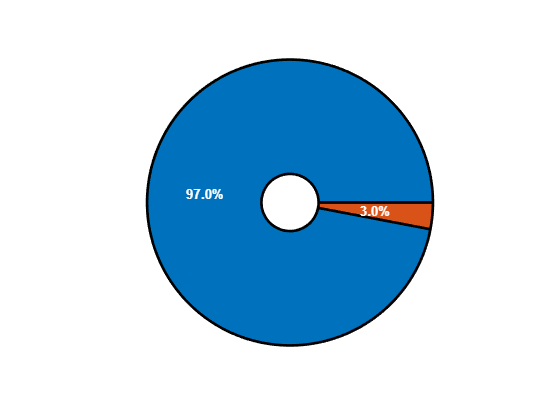

MATLAB.Graphics.NestedPie({[97,3]},LabelText=[]);

## PLine

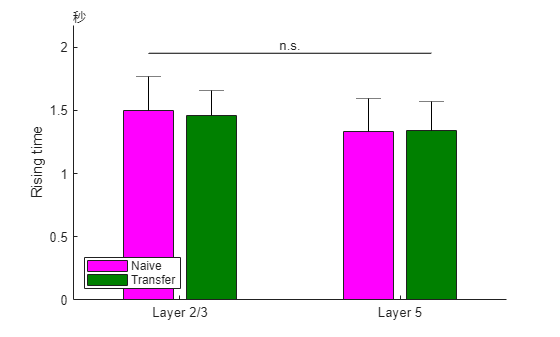

load('+MATLAB\+Graphics\PLine.mat');
figure;
Bars=bar(ActiveLightRising{["MOp2/3","MOp5"],["NaiveLight","Transfer"],"Mean"});
colororder([1,0,1;0,0.5,0]);
Ax=gca;
Ax.Units='points';
hold on;
EBs=errorbar(vertcat(Bars.XEndPoints).',ActiveLightRising{["MOp2/3","MOp5"],["NaiveLight","Transfer"],"Mean"},[],ActiveLightRising{["MOp2/3","MOp5"],["NaiveLight","Transfer"],"Sem"},CapSize=Ax.Position(3)*Bars(1).GroupWidth*Bars(1).BarWidth/(numel(Bars)*diff(xlim)*2),Color='k',LineStyle='none');
xticks(1:2);
xticklabels(["Layer 2/3","Layer 5"]);
box off;
MATLAB.Graphics.PLine(table(EBs(1),EBs(end),1,2,"n.s.",'VariableNames',["ObjectA","ObjectB","IndexA","IndexB","Text"]));
xlabel(Layout,'Time from 💡(:)💧(|)');
ylim([0,diff(ylim)]);
ylabel('Rising time');
legend(Bars,["Naive","Transfer"],Location=MATLAB.Graphics.OptimizedLegendLocation(Bars));

## Venn

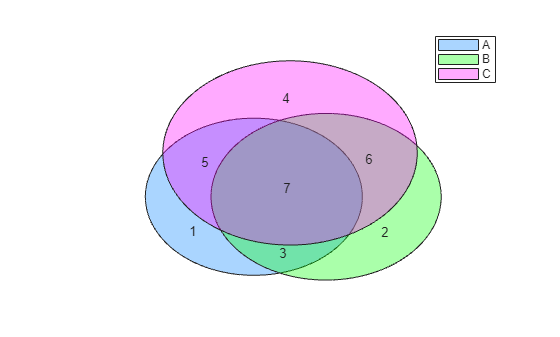

figure;
Data=reshape(0:7,2,2,2);
legend(MATLAB.Graphics.Venn(Data,string(Data)),["A","B","C"]);
axis off

# IO

创建快捷方式

MATLAB.IO.LnkShortcut('C:\sdl');

将文件或目录批量移动到回收站

MATLAB.IO.Delete('.');

## FindLocking/CloseHandle

FilePath='示例.txt'

FilePath = '示例.txt'

Fid=fopen(FilePath,'w');

[Handle,ProcessId]=MATLAB.IO.FindLocking(FilePath)


Handle =

  空的 0×1 uint64 列向量


ProcessId =

  空的 0×1 uint32 列向量



%决定关闭句柄之前，通常应用任务管理器等其它工具检查受影响的进程有哪些。尽管那些进程不会被直接关闭，但意外关闭的文件句柄可能导致那些进程产生意外行为。
MATLAB.IO.CloseHandle(Handle,ProcessId);

fclose(Fid);

错误使用 fclose
文件标识符无效。使用 fopen 生成有效的文件标识符。

%fclose会出错，因为底层句柄已关闭

# IOFun

## File

import MATLAB.Flags
%创建文件
F=MATLAB.IOFun.File('文件.文件',CreationDisposition=Flags.OPEN_ALWAYS,DesiredAccess=Flags.GENERIC_WRITE+Flags.GENERIC_READ);
%写出数据
F.Write(1:10);
%获取当前文件指针
F.SetPointer

ans = int64
80

%设置文件指针
F.SetPointer(0);
%读入数据
F.Read(10,MATLAB.DataTypes.ArrayType.DOUBLE);
%扩展文件
F.SetPointer(300);
F.SetEnd;
%使用完后会自动清理，也可以手动delete，将关闭文件
clearvars F

## MemoryMapping

内存映射，可以基于磁盘文件，也可以是纯内存。赋予一个名称后可以跨进程传递数据

import MATLAB.Flags
Name='MATLAB内存映射测试';
%创建内存映射文件，填充初始值并获取指针
[MM,P]=MATLAB.IOFun.MemoryMapping.Create(Name=Name,FillData=rand(8,1));
%读指针
P.Read(8,MATLAB.DataTypes.ArrayType.DOUBLE)

ans =     0.4387
    0.3816
    0.7655
    0.7952
    0.1869
    0.4898
    0.4456
    0.6463


%在其它进程读入这段内存之前，请保持内存映射对象持续存在

新开一个MATLAB会话，尝试读入这段内存：

import MATLAB.Flags
Name='MATLAB内存映射测试';
%用相同名称创建内存映射，同时获取指针
[MM,P]=MATLAB.IOFun.MemoryMapping.Open(Name);
%从指针读出数据，观察和写入的是否相同
P.Read(8,MATLAB.DataTypes.ArrayType.DOUBLE)

ans =     0.4387
    0.3816
    0.7655
    0.7952
    0.1869
    0.4898
    0.4456
    0.6463


%内存映射对象可以自动释放，当然你也可以手动释放
delete(MM);
%此释放仅限本进程。只有所有进程都释放了同样名称的内存映射对象，才会在系统级别彻底释放这块内存。

FilePath = '示例.txt'

Handle = 3×1 uint64 列向量
    9144
   10888
   11788


ProcessId = 3×1 uint32 列向量
   23452
   23452
   23452


错误使用 fclose
无法写入位置 '示例.txt'。
'Bad file descriptor'。

# Lang

## BuiltinBugFix

显示所有支持修复的bug

MATLAB.Lang.BuiltinBugFix

ans = 3×1 string 数组
    "doc无法打开多个帮助窗口"
    "edit无法打开含有非ASCII字符的主机名SMB共享的.m代码文件"
    "打包为工具箱时访问美国服务器失败，也不尝试中国CDN"


示例：修复doc无法打开多个帮助窗口的bug

doc MATLAB.IOFun.File
doc MATLAB.IOFun.MemoryMapping

上述两行只会打开一个帮助窗口，File会被MemoryMapping覆盖。现在修复此问题，将需要提权和重启：

MATLAB.Lang.BuiltinBugFix(2);

输入参数是2，因为“doc无法打开多个帮助窗口”是排在第2号的bug

重启后尝试验证bug是否修复：

doc MATLAB.IOFun.File
doc MATLAB.IOFun.MemoryMapping

如果修复成功，上述两行将分别打开File和MemoryMapping的两个帮助窗口

此补丁还可以还原，只需将补丁号改为对应的负数，同样需要提权和重启

MATLAB.Lang.BuiltinBugFix(-2);

错误使用 WindowsCall
MATLAB:Exception:Failed_to_communicate_with_the_privilege_server：管道已结束。


出错 MATLAB.internal.WindowsAPI/Call (第 57 行)
			[varargout{1:nargout}]=WindowsCall(uint64(obj),varargin{:});

出错 MATLAB.Lang.BuiltinBugFix (

可以指定数组，一次性修复所有问题：

MATLAB.Lang.BuiltinBugFix(1:3);

卸载补丁

MATLAB.Lang.BuiltinBugFix(-5:-1);

## IEnumerableException

方便地抛出异常

MATLAB.Exception.Example_exception.Throw;

MATLAB:Lang:MatlabException:Example_exception

也可以作为警告抛出

MATLAB.Exception.Example_exception.Warn;

# Project

## AssociatePrjExtension

将prj文件扩展名关联到MATLAB（默认不关联），执行以后可以直接在文件资源管理器中双击打开prj文件唤起MATLAB

MATLAB.Project.AssociatePrjExtension;

# RandFun

## Shuffle

允许设置最大连续重复数的洗牌算法

Statistics=dictionary;
for a=1:10000
	Shuffle=MATLAB.RandFun.Shuffle('aaaabbbcc',MaxConsecutiveRepeats=1);
	if Statistics.isConfigured&&Statistics.isKey(Shuffle)
		Statistics(Shuffle)=Statistics(Shuffle)+1;
	else
		Statistics(Shuffle)=1;
	end
end